## 加载数据，总共7个类型  

## 请打开文件夹路径为\E:\医学物理\待投稿论文\Dosiomics\Type-7-MAT加载数据

folderpath = uigetdir('E:\医学物理\待投稿论文\Dosiomics','Please select a file to improt');
%创建ImmageDatastore对象，自动将子文件夹名称作为标签
Data_all = imageDatastore(folderpath,'IncludeSubfolders',true,'FileExtensions','.mat','ReadFcn',@(x) matRead(x),'LabelSource','foldernames');

[Data_Train,Data_Test] = splitEachLabel(Data_all,0.8,0.2,'randomized'); %80%训练 20%测试  随机划分

%显示当前所有数据集，训练集和测试集的数据大小

%所有标签数目汇总
Label_all = countEachLabel(Data_all)%按类别统计图像

Label_all = 7×2 table
       Label       Count
    ___________    _____

    BodyChanges     279 
    ErrorFree       279 
    Gantry          372 
    MLCR            279 
    MLCS            372 
    MU              372 
    SETUP           558 


Label_Train = countEachLabel(Data_Train) %训练集类别统计

Label_Train = 7×2 table
       Label       Count
    ___________    _____

    BodyChanges     223 
    ErrorFree       223 
    Gantry          298 
    MLCR            223 
    MLCS            298 
    MU              298 
    SETUP           446 


Label_Test = countEachLabel(Data_Test) %验证类别统计

Label_Test = 7×2 table
       Label       Count
    ___________    _____

    BodyChanges      56 
    ErrorFree        56 
    Gantry           74 
    MLCR             56 
    MLCS             74 
    MU               74 
    SETUP           112 


%Label_Test = countEachLabel(Data_Test)  %测试集类别统计
cvp = cvpartition(Data_Train.Labels,'KFold',5,'Stratify',true);  %五折交叉验证  分层抽样 确保每这种各类别与完整数据集相同

## 第一次交叉验证

Train_idx1 = training(cvp,1); %第一次训练集样本索引
Test_idx1 = test(cvp,1);
imdsTrain_1 = subset(Data_Train, Train_idx1);%获取训练集样本
imdsVal_1 = subset(Data_Train,Test_idx1);%获取测试集样本
Train_num = countEachLabel(imdsTrain_1)

Train_num = 7×2 table
       Label       Count
    ___________    _____

    BodyChanges     179 
    ErrorFree       178 
    Gantry          239 
    MLCR            178 
    MLCS            238 
    MU              239 
    SETUP           357 


Test_num =countEachLabel(imdsVal_1)

Test_num = 7×2 table
       Label       Count
    ___________    _____

    BodyChanges     44  
    ErrorFree       45  
    Gantry          59  
    MLCR            45  
    MLCS            60  
    MU              59  
    SETUP           89  


Network=resnet50TL3Dfun();%运行预先训练的网络
FClayerName ='fc1000';
outputLayerName = 'ClassificationLayer_fc1000';
newFClayer = fullyConnectedLayer(7,'Name','new_fc7','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
newOutputLayer = classificationLayer('Name','New_classoutput');
%替换层
Network = replaceLayer(Network,FClayerName,newFClayer);
Network = replaceLayer(Network,outputLayerName,newOutputLayer);
%analyzeNetwork(Network);

layers = Network.Layers

layers =   具有以下层的 177×1 Layer 数组:

     1   'input_1'              三维图像输入      224×224×224×1 图像: 'zerocenter' 归一化
     2   'conv1'                三维卷积         64 7×7×7×1 卷积: 步幅 [2  2  2]，填充 [3  3  3; 3  3  3]
     3   'bn_conv1'             批量归一化        批量归一化: 64 个通道
     4   'activation_1_relu'    ReLU            ReLU
     5   'max_pooling3d_1'      三维最大池化      3×3×3 最大池化: 步幅 [2  2  2]，填充 [0  0  0; 0  0  0]
     6   'res2a_branch1'        三维卷积         256 1×1×1×64 卷积: 步幅 [1  1  1]，填充 [0  0  0; 0  0  0]
     7   'bn2a_branch1'         批量归一化        批量归一化: 256 个通道
     8   'res2a_branch2a'       三维卷积         64 1×1×1×64 卷积: 步幅 [1  1  1]，填充 [0  0  0; 0  0  0]
     9   'bn2a_branch2a'        批量归一化        批量归一化: 64 个通道
    10   'activation_2_relu'    ReLU            ReLU
    11   'res2a_branch2b'       三维卷积         64 3×3×3×64 卷积: 步幅 [1  1  1]，填充 'same'
    12   'bn2a_branch2b'        批量归一化        批量归一化: 64 个通道


%{
connnections = Network.Connections;
for  i = 1:numel(layers)
    if isa(layers(i),'FullyConnectedLayer') && strcmp(layers(i).Name,'new_fc7')
        continue;
    end

    if isprop(layers(i),'WeightLearnRateFactor')
        layers(i).WeightLearnRateFactor = 0;
    end

    if isprop(layers(i),'BiasLearnRateFactor')
        layers(i).BiasLearnRateFactor = 0;
    end
end
%}

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：０６：１７　｜　　　１２．５０％　｜　　４８．３８％　｜　　２．０５４４　｜　１．５９４７　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　５０　｜　　　　　０２：４０：２２　｜　　１００．００％　｜　　８７．０３％　｜　　０．１１３７　｜　０．３５２８　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　１００　｜　　　　　０５：１８：１１　｜　　　７５．００％　｜　　８９．０３％　｜　　０．４８６０　｜　０．２６９２　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　１５０　｜　　　　　０７：５５：５９　｜　　　８７．５０％　｜　　９０．５２％　｜　　０．３２７４　｜　０．２２１３　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　２００　｜　　　　　１０：３３：５０　｜　　　８７．５０％　｜　　８９．７８％　｜　　０．３１５９　｜　０．２３３４　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　２５０　｜　　　　　１３：１１：４３　｜　　　８７．５０％　｜　　８９．０３％　｜　　０．２５７４　｜　０．３０３５　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　３００　｜　　　　　１５：４９：４９　｜　　１００．００％　｜　　８８．５３％　｜　　０．０１５７　｜　０．３２０９　｜　１．００００ｅ－０４　｜
｜　　　４　｜　　３５０　｜　　　　　１８：２９：２３　｜　　　８７．５０％　｜　　９１．０２％　｜　　０．５６６３　｜　０．２２６２　｜　１．００００ｅ－０４　｜
｜　

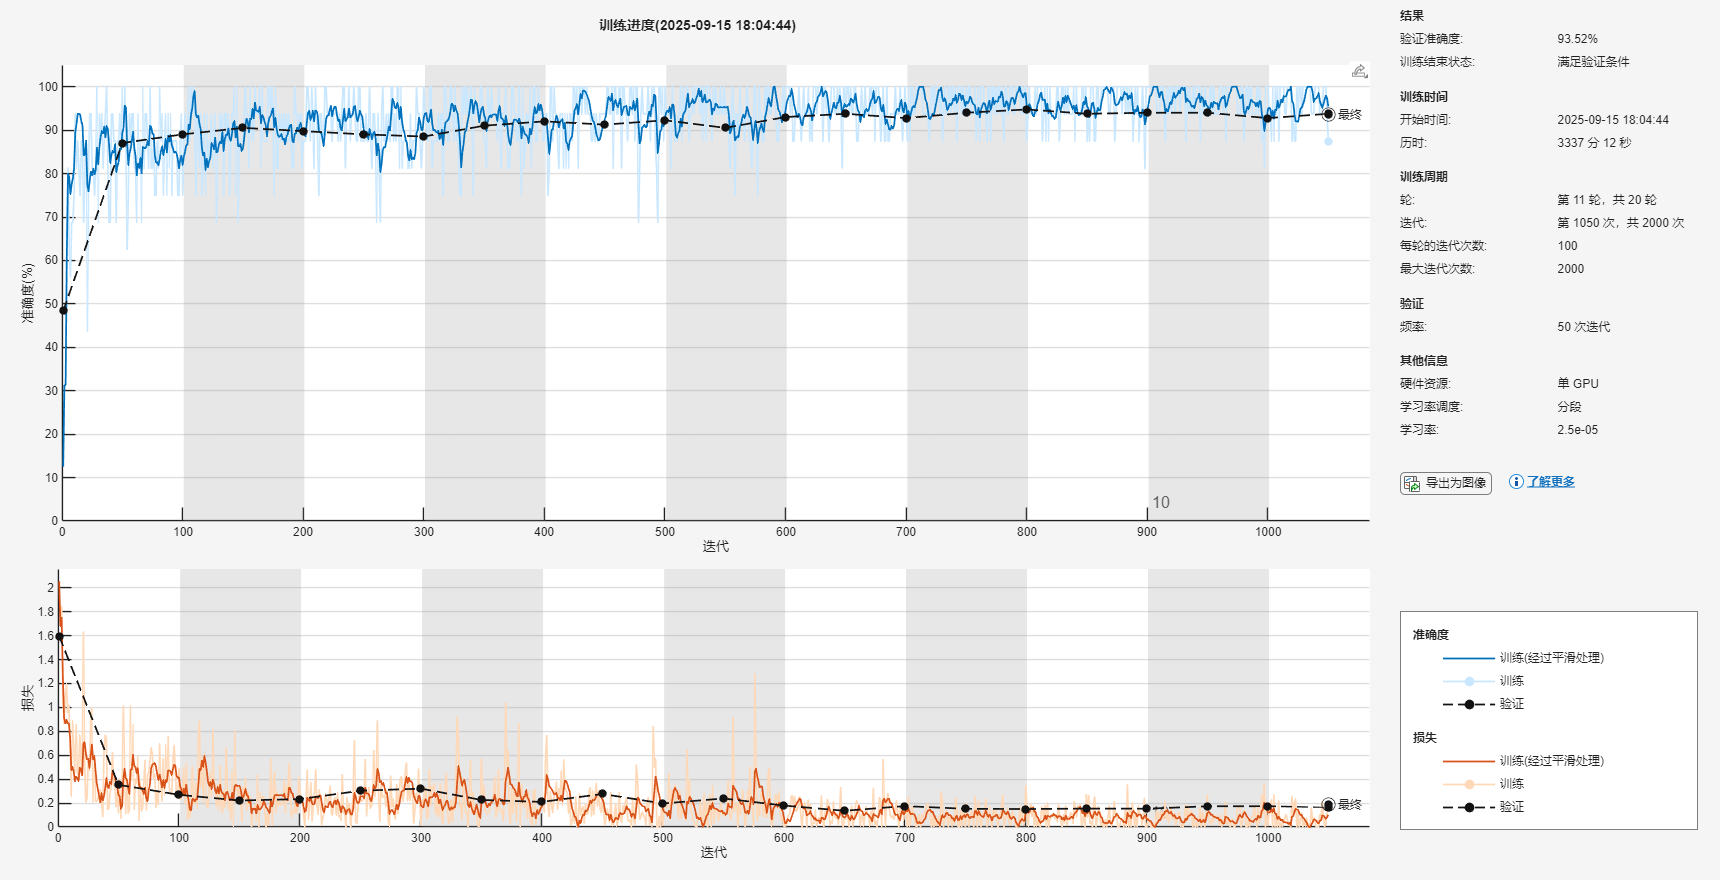

options=trainingOptions('adam',...
    'Plots','training-progress',...
    'MiniBatchSize',16,...
    'InitialLearnRate',0.0001,...
    'MaxEpochs',20,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor',0.5,...
    'LearnRateDropPeriod',5,...
    'ValidationPatience',8,...
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment','gpu',...
    "OutputNetwork","last-iteration",...
    'ValidationData',imdsVal_1);
[net,traininfo]=trainNetwork(imdsTrain_1,Network,options);

modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));  
save(strcat("3DRESNetCV1-",modelDateTime,".mat"),'net'); %保存模型
save(strcat("3DRESNetCV1info-",modelDateTime,".mat"),'traininfo'); %保存训练信息

## 第2折训练

load("DP_data.mat"); %加载数据
Train_idx2 = training(cvp,2); %第二次训练集样本索引
Test_idx2 = test(cvp,2);
imdsTrain_2 = subset(Data_Train, Train_idx2);%获取训练集样本
imdsVal_2 = subset(Data_Train,Test_idx2);%获取测试集样本


Network=resnet50TL3Dfun();%运行预先训练的网络
FClayerName ='fc1000';
outputLayerName = 'ClassificationLayer_fc1000';
newFClayer = fullyConnectedLayer(7,'Name','new_fc7','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
newOutputLayer = classificationLayer('Name','New_classoutput');
%替换层
Network = replaceLayer(Network,FClayerName,newFClayer);
Network = replaceLayer(Network,outputLayerName,newOutputLayer);

%训练参数
options=trainingOptions('adam',...
    'Plots','training-progress',...
    'MiniBatchSize',16,...
    'InitialLearnRate',0.0001,...
    'MaxEpochs',20,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor',0.5,...
    'LearnRateDropPeriod',5,...
    'ValidationPatience',8,...
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment','gpu',...
    "OutputNetwork","last-iteration",...
    'ValidationData',imdsVal_2);

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：０５：３８　｜　　　１２．５０％　｜　　３２．５９％　｜　　２．１８５１　｜　１．８７８２　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　５０　｜　　　　　０２：３７：１３　｜　　　６８．７５％　｜　　８２．０９％　｜　　０．５２２１　｜　０．５２９３　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　１００　｜　　　　　０５：１２：５０　｜　　　９３．７５％　｜　　８９．０５％　｜　　０．２５１１　｜　０．２９６９　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　１５０　｜　　　　　０７：４８：４６　｜　　　７５．００％　｜　　９０．５５％　｜　　１．１１７６　｜　０．２５２８　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　２００　｜　　　　　１０：２４：３８　｜　　１００．００％　｜　　９０．８０％　｜　　０．０３３６　｜　０．２４０９　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　２５０　｜　　　　　１２：５９：４６　｜　　　８１．２５％　｜　　９２．２９％　｜　　０．３９９１　｜　０．２０６３　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　３００　｜　　　　　１５：３４：４５　｜　　　８７．５０％　｜　　８９．８０％　｜　　０．２３７６　｜　０．３９６５　｜　１．００００ｅ－０４　｜
｜　　　４　｜　　３５０　｜　　　　　１８：１０：５１　｜　　　９３．７５％　｜　　９１．０４％　｜　　０．１５２６　｜　０．３９２７　｜　１．００００ｅ－０４　｜
｜　

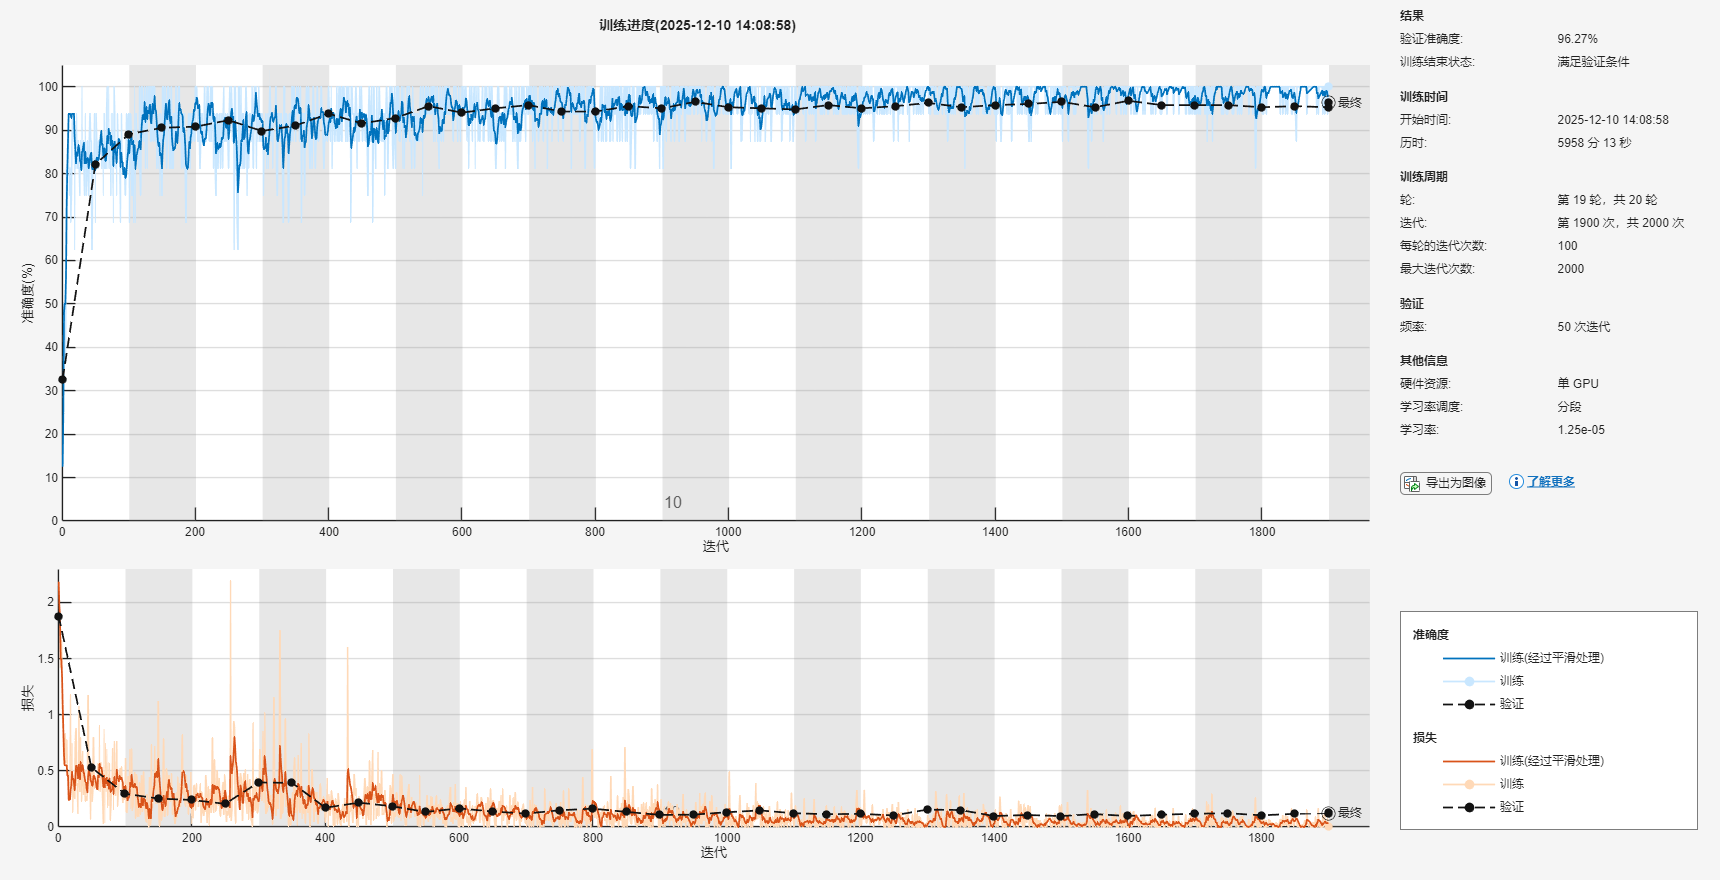

%开始训练
[net,traininfo]=trainNetwork(imdsTrain_2,Network,options);

%保存训练2折训练模型的结果
modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));  
save(strcat("3DRESNetCV2-",modelDateTime,".mat"),'net'); %保存模型
save(strcat("3DRESNetCV2info-",modelDateTime,".mat"),'traininfo'); %保存训练信息

## 第三折训练

load("DP_data.mat"); %加载数据
Train_idx3 = training(cvp,3); %第三次训练集样本索引
Test_idx3 = test(cvp,3);
imdsTrain_3 = subset(Data_Train, Train_idx3);%获取训练集样本
imdsVal_3 = subset(Data_Train,Test_idx3);%获取测试集样本

Network=resnet50TL3Dfun();%运行预先训练的网络
FClayerName ='fc1000';
outputLayerName = 'ClassificationLayer_fc1000';
newFClayer = fullyConnectedLayer(7,'Name','new_fc7','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
newOutputLayer = classificationLayer('Name','New_classoutput');
%替换层
Network = replaceLayer(Network,FClayerName,newFClayer);
Network = replaceLayer(Network,outputLayerName,newOutputLayer);

%训练参数
options=trainingOptions('adam',...
    'Plots','training-progress',...
    'MiniBatchSize',16,...
    'InitialLearnRate',0.0001,...
    'MaxEpochs',20,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor',0.5,...
    'LearnRateDropPeriod',5,...
    'ValidationPatience',8,...
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment','gpu',...
    "OutputNetwork","last-iteration",...
    'ValidationData',imdsVal_3);

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：０５：０６　｜　　　　６．２５％　｜　　４０．７５％　｜　　２．０６９６　｜　１．７８３７　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　５０　｜　　　　　０２：３３：１８　｜　　　６８．７５％　｜　　９５．９５％　｜　　０．８２０７　｜　０．１４８０　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　１００　｜　　　　　０５：０４：２０　｜　　１００．００％　｜　　９７．６９％　｜　　０．０５９１　｜　０．１４０９　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　１５０　｜　　　　　０７：３５：２５　｜　　１００．００％　｜　　９６．８２％　｜　　０．０００３　｜　０．１４６８　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　２００　｜　　　　　１０：０６：１３　｜　　１００．００％　｜　　９７．９８％　｜　　０．００９６　｜　０．０７５２　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　２５０　｜　　　　　１２：３７：０７　｜　　１００．００％　｜　　９６．２４％　｜　　０．１５９２　｜　０．１９９４　｜　１．００００ｅ－０４　｜
｜　　　４　｜　　３００　｜　　　　　１５：０７：３３　｜　　　９３．７５％　｜　　９７．９８％　｜　　０．２５３０　｜　０．１０９９　｜　１．００００ｅ－０４　｜
｜　　　５　｜　　３５０　｜　　　　　１７：３８：５１　｜　　１００．００％　｜　　９５．９５％　｜　　０．００４９　｜　０．３７８９　｜　１．００００ｅ－０４　｜
｜　

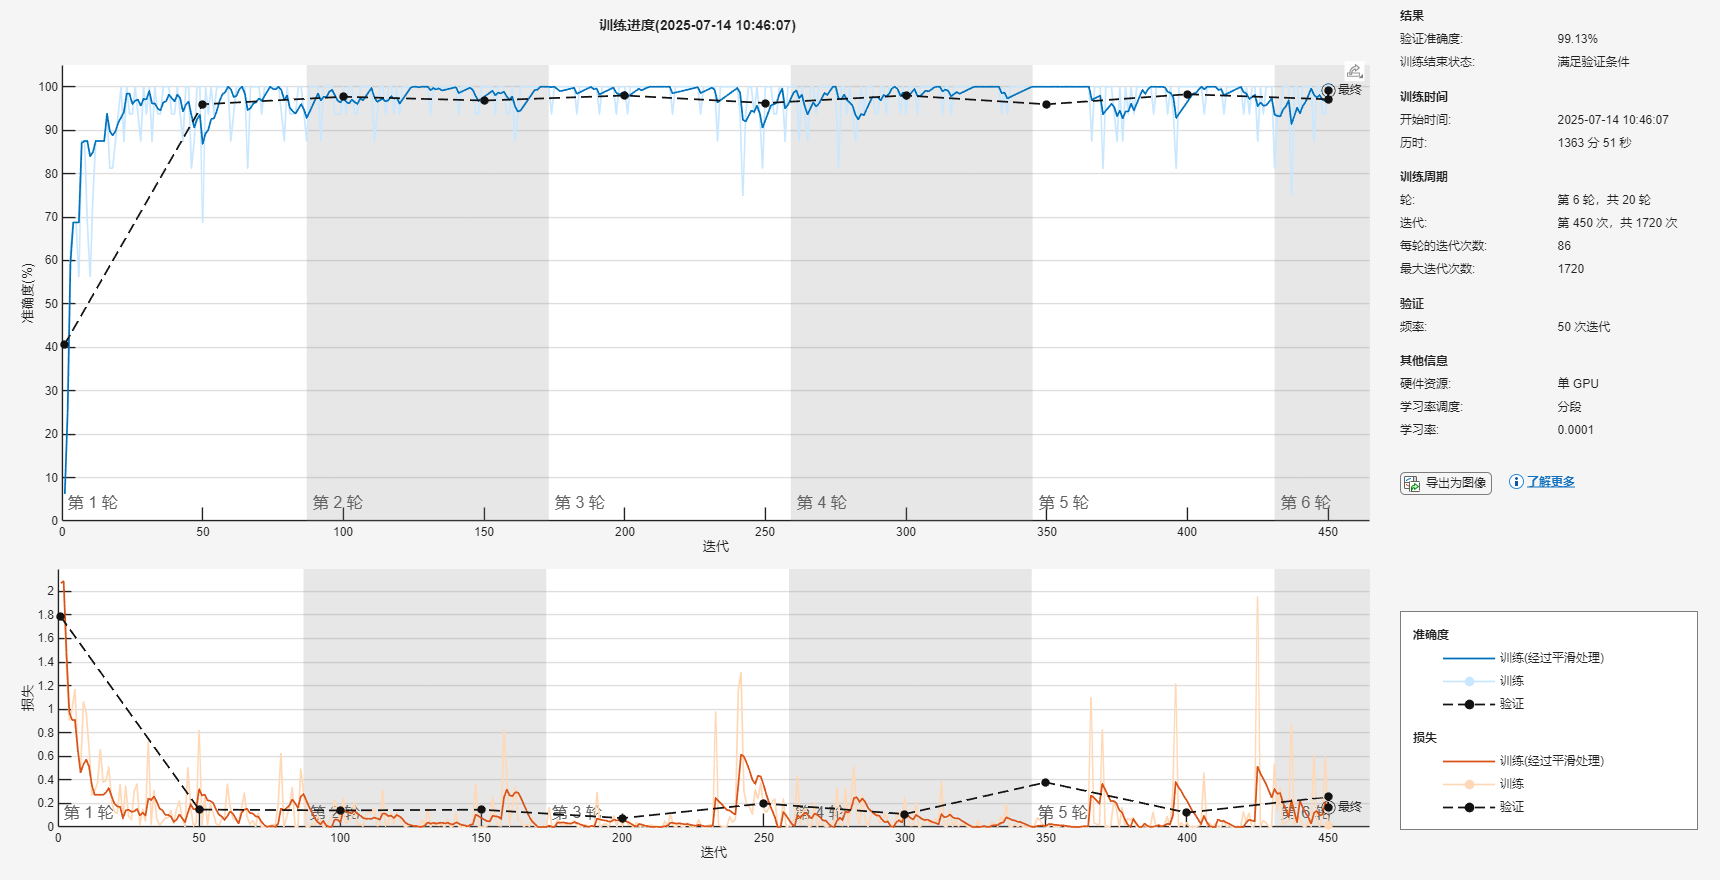

%开始训练
[net,traininfo]=trainNetwork(imdsTrain_3,Network,options);

%保存训练2折训练模型的结果
modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));  
save(strcat("3DRESNetCV3-",modelDateTime,".mat"),'net'); %保存模型
save(strcat("3DRESNetCV3info-",modelDateTime,".mat"),'traininfo'); %保存训练信息

## 第四折训练

load("DP_data.mat"); %加载数据
Train_idx4 = training(cvp,4); %第四次训练集样本索引
Test_idx4 = test(cvp,4);
imdsTrain_4 = subset(Data_Train, Train_idx4);%获取训练集样本
imdsVal_4 = subset(Data_Train,Test_idx4);%获取测试集样本

Network=resnet50TL3Dfun();%运行预先训练的网络
FClayerName ='fc1000';
outputLayerName = 'ClassificationLayer_fc1000';
newFClayer = fullyConnectedLayer(7,'Name','new_fc7','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
newOutputLayer = classificationLayer('Name','New_classoutput');
%替换层
Network = replaceLayer(Network,FClayerName,newFClayer);
Network = replaceLayer(Network,outputLayerName,newOutputLayer);

%训练参数
options=trainingOptions('adam',...
    'Plots','training-progress',...
    'MiniBatchSize',16,...
    'InitialLearnRate',0.0001,...
    'MaxEpochs',20,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor',0.5,...
    'LearnRateDropPeriod',5,...
    'ValidationPatience',8,...
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment','gpu',...
    "OutputNetwork","last-iteration",...
    'ValidationData',imdsVal_4);

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：０５：５１　｜　　　　０．００％　｜　　３３．３３％　｜　　２．２９６１　｜　１．８８５９　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　５０　｜　　　　　０２：３７：５２　｜　　　７５．００％　｜　　８５．５７％　｜　　０．５４０３　｜　０．４０１６　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　１００　｜　　　　　０５：１２：５６　｜　　１００．００％　｜　　８７．３１％　｜　　０．０８２８　｜　０．３４６３　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　１５０　｜　　　　　０７：４８：３０　｜　　　８７．５０％　｜　　８８．８１％　｜　　０．８００７　｜　０．３６０５　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　２００　｜　　　　　１０：２３：３０　｜　　　９３．７５％　｜　　８７．０６％　｜　　０．１９３９　｜　０．２９７８　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　２５０　｜　　　　　１２：５９：０３　｜　　　８１．２５％　｜　　９０．３０％　｜　　０．３７５７　｜　０．２８６８　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　３００　｜　　　　　１５：３４：００　｜　　１００．００％　｜　　９０．３０％　｜　　０．０８７３　｜　０．２６３９　｜　１．００００ｅ－０４　｜
｜　　　４　｜　　３５０　｜　　　　　１８：０８：４６　｜　　　８７．５０％　｜　　９０．３０％　｜　　０．３１９２　｜　０．２３８５　｜　１．００００ｅ－０４　｜
｜　

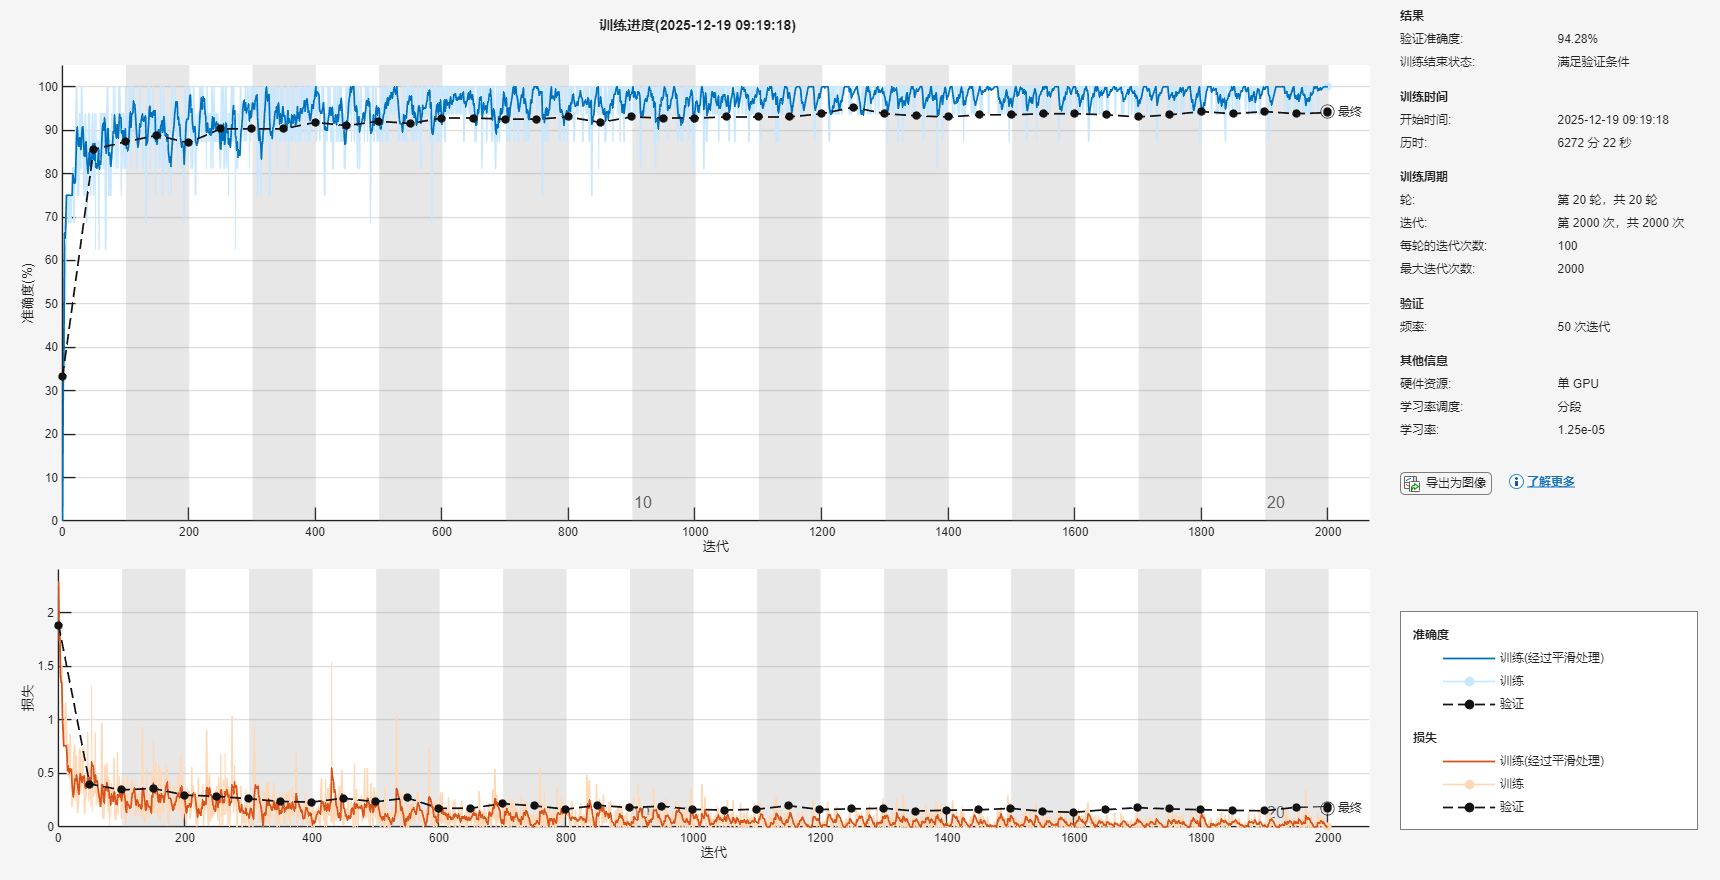

%开始训练
[net,traininfo]=trainNetwork(imdsTrain_4,Network,options);

%保存训练4折训练模型的结果
modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));  
save(strcat("3DRESNetCV4-",modelDateTime,".mat"),'net'); %保存模型
save(strcat("3DRESNetCV4info-",modelDateTime,".mat"),'traininfo'); %保存训练信息

## 第五折训练

load("DP_data.mat"); %加载数据
Train_idx5 = training(cvp,5); %第五次训练集样本索引
Test_idx5 = test(cvp,5);
imdsTrain_5 = subset(Data_Train, Train_idx5);%获取训练集样本
imdsVal_5 = subset(Data_Train,Test_idx5);%获取测试集样本

Network=resnet50TL3Dfun();%运行预先训练的网络
FClayerName ='fc1000';
outputLayerName = 'ClassificationLayer_fc1000';
newFClayer = fullyConnectedLayer(7,'Name','new_fc7','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
newOutputLayer = classificationLayer('Name','New_classoutput');
%替换层
Network = replaceLayer(Network,FClayerName,newFClayer);
Network = replaceLayer(Network,outputLayerName,newOutputLayer);

%训练参数
options=trainingOptions('adam',...
    'Plots','training-progress',...
    'MiniBatchSize',16,...
    'InitialLearnRate',0.0001,...
    'MaxEpochs',20,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor',0.5,...
    'LearnRateDropPeriod',5,...
    'ValidationPatience',8,...
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment','gpu',...
    "OutputNetwork","last-iteration",...
    'ValidationData',imdsVal_5);

正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：０５：３８　｜　　　　０．００％　｜　　３０．１０％　｜　　２．２７２６　｜　１．８６５５　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　　５０　｜　　　　　０２：３７：１４　｜　　　７５．００％　｜　　８７．０６％　｜　　０．５７７０　｜　０．３７５３　｜　１．００００ｅ－０４　｜
｜　　　１　｜　　１００　｜　　　　　０５：１１：５９　｜　　　８７．５０％　｜　　８６．５７％　｜　　０．２６８２　｜　０．４０７３　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　１５０　｜　　　　　０７：４７：２７　｜　　　７５．００％　｜　　８６．８２％　｜　　０．４８７２　｜　０．４００７　｜　１．００００ｅ－０４　｜
｜　　　２　｜　　２００　｜　　　　　１０：２３：１０　｜　　　９３．７５％　｜　　９０．５５％　｜　　０．１７２２　｜　０．２５０１　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　２５０　｜　　　　　１２：５８：４０　｜　　　７５．００％　｜　　９１．５４％　｜　　０．７４３４　｜　０．２２６９　｜　１．００００ｅ－０４　｜
｜　　　３　｜　　３００　｜　　　　　１５：３４：５７　｜　　　８７．５０％　｜　　９０．８０％　｜　　０．２６５８　｜　０．２４８１　｜　１．００００ｅ－０４　｜
｜　　　４　｜　　３５０　｜　　　　　１８：１０：１３　｜　　１００．００％　｜　　９１．５４％　｜　　０．１５９６　｜　０．２１８２　｜　１．００００ｅ－０４　｜
｜　

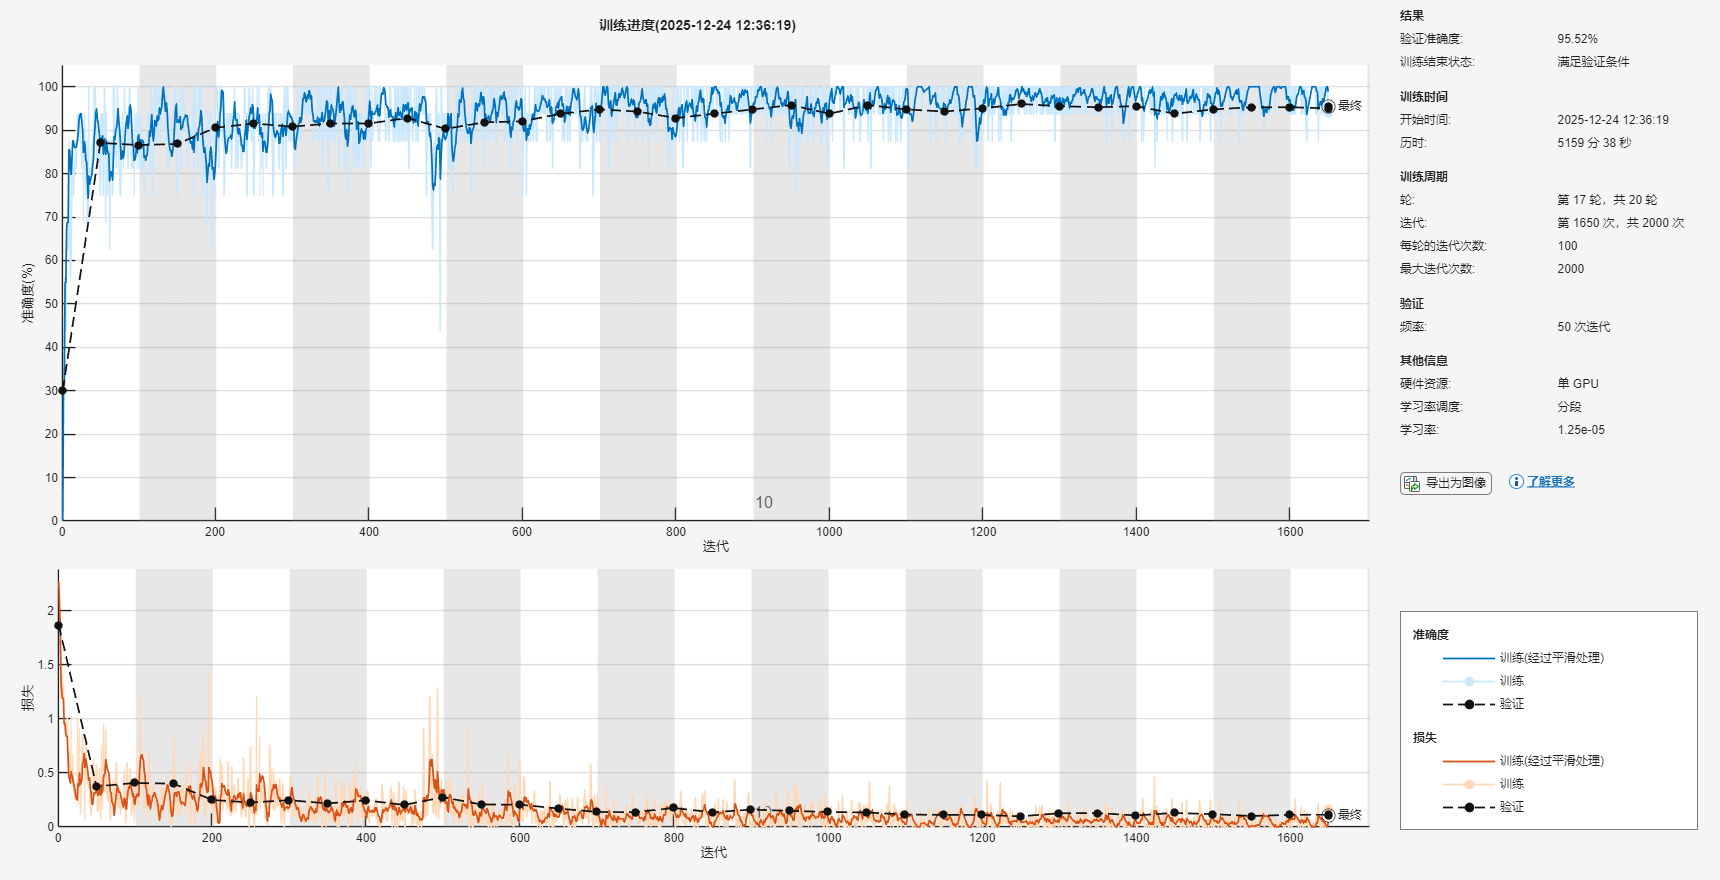

%开始训练
[net,traininfo]=trainNetwork(imdsTrain_5,Network,options);

%保存训练4折训练模型的结果
modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));  
save(strcat("3DRESNetCV5-",modelDateTime,".mat"),'net'); %保存模型
save(strcat("3DRESNetCV5info-",modelDateTime,".mat"),'traininfo'); %保存训练信息

## 五折交叉验证及测试集结果

load("DP_data.mat"); %加载数据

DPmodels = cell(1,cvp.NumTestSets);%初始化 cell用于保存五折交叉验证所得到的每个DeepModel
Metrics_Deep_Array = repmat(table, 1,cvp.NumTestSets); %预先分配table数组用于存储评估指标

%%依次加载训练好的模型
DPmodels{1} = load("3DRESNetCV1-2025-09-18-01-51-03.mat");
DPmodels{2} = load("3DRESNetCV2-2025-12-14-17-35-53.mat");
DPmodels{3} = load("3DRESNetCV3-2025-12-18-21-07-23.mat");
DPmodels{4} = load("3DRESNetCV4-2025-12-23-18-00-19.mat");
DPmodels{5} = load("3DRESNetCV5-2025-12-28-02-44-33.mat");

%五折交叉验证
for fold = 1:cvp.NumTestSets
    Val_idx = test(cvp, fold); %抓取验证集的index;
    Val_data = subset(Data_Train, Val_idx); %获取验证的数据集

    %验证获得预测标签
    [predictedLabels, ~]=classify(DPmodels{fold}.net,Val_data,...
        'ExecutionEnvironment','cpu','MiniBatchSize',32);

    %获得混淆矩阵
    CM_Val_fold=confusionmat(Val_data.Labels,predictedLabels);
    DPVal_classnum = numel(unique(Val_data.Labels));%获取类别数目
    
    Metrics_Deep_Array(fold,:) = Eval_Metrics(CM_Val_fold, DPVal_classnum);  
    %获得每折评估指标
end
%计算最终的平均评估指标
metrics_deepVal = mean(Metrics_Deep_Array); %求平均值
fprintf('训练集五折交叉验证准确率 %.2f %%.\n', metrics_deepVal.accuracy);

训练集五折交叉验证准确率 95.27 %.


fprintf('训练集五折交叉验证精确率 %.4f.\n', metrics_deepVal.MacroPrecision);

训练集五折交叉验证精确率 0.9555.


fprintf('训练集五折交叉验证召回率 %.4f.\n', metrics_deepVal.MacroRecall);

训练集五折交叉验证召回率 0.9552.


fprintf('训练集五折交叉验证F1分数 %.4f.\n', metrics_deepVal.MacroF1);

训练集五折交叉验证F1分数 0.9542.


## 独立测试集数据进行测试

%测试集测试数据+
[metrics_DP_Test, Pred_DP_Test, Score_DP_Test] = EvalDeepModel(DPmodels,Data_Test);

训练集五折交叉验证准确率 95.22 %.
训练集五折交叉验证精确率 0.9558.
训练集五折交叉验证召回率 0.9514.
训练集五折交叉验证F1分数 0.9524.


## 临床测试数据结果

%加载临床测试集数据
load("Data_ClinicTest.mat");

%测试集测试数据
[metrics_DP_CTest, Pred_DP_CTest, Score_DP_CTest] = EvalDeepModel(DPmodels,Data_clinic_Test);

函数或变量 'DPmodels' 无法识别。

## 画混淆矩阵

load("DeepTESTData.mat");

%%独立测试混淆矩阵
Pred_DP_Test = removecats(Pred_DP_Test, '0'); %移除冗余的类别
className = categories(Pred_DP_Test);

figure;
confmat = confusionchart(Data_Test.Labels, Pred_DP_Test);
confmat.Normalization = 'total-normalized';
confmat.RowSummary = 'row-normalized';
confmat.ColumnSummary = 'column-normalized';
[cm_test_level1,order_test_level1] = confusionmat(Data_Test.Labels, Pred_DP_Test);

%% 临床测试混淆矩阵
Pred_DP_CTest = removecats(Pred_DP_CTest, '0'); %移除冗余的类别

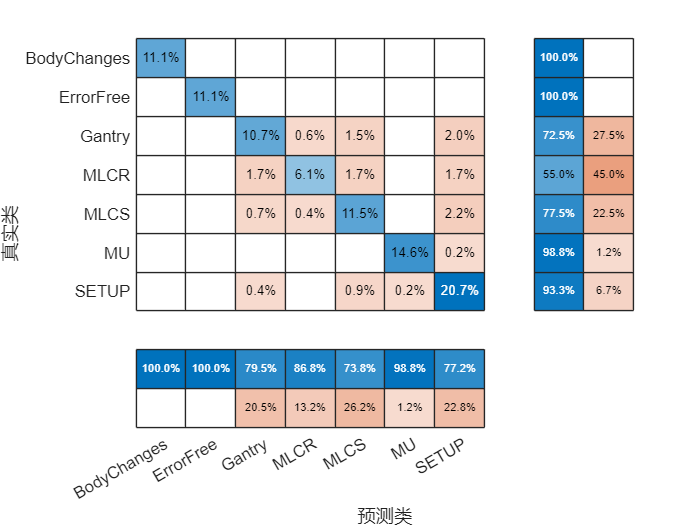

figure(2);
confmat = confusionchart(Data_clinic_Test.Labels, Pred_DP_CTest);
confmat.Normalization = 'total-normalized';
confmat.RowSummary = 'row-normalized';
confmat.ColumnSummary = 'column-normalized';

[cm_ctest_level1,order_Ctest_level1] = confusionmat(Data_clinic_Test.Labels, Pred_DP_CTest);